# **Lab 5: Segmentació**

## **Xavier Martín Ballesteros i Adrià Cabeza Sant'Anna**

## Region Growing 

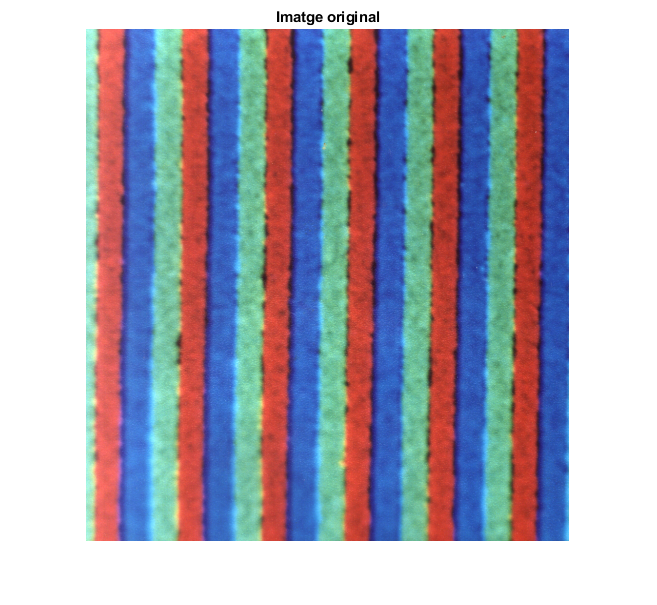

global im eti MAXFILA MAXCOL TH seedVal
TH = 150;
im = imread('Ipces01.tif');
[MAXFILA MAXCOL nchan] = size(im);
eti = zeros(MAXFILA, MAXCOL);
imshow(im), title('Imatge original')

seedVal = im(18, 252, :);

#### Region Growing function 

type RG.m


function RG(fila, col, label)
% Segmentació utilitzant la tècnica Region Growing. Necessita fila, columna
% i el label. 
    global im eti MAXFILA MAXCOL TH seedVal
    
    eti(fila, col) = label;
%     val = im(fila, col, :); en el cas que fem servir el valor del pare no
%     de la llavor. Si l'haguéssim utilitzat hauríem hagut de fer la
%     següent crida sum(imabsdiff(val, pxVal))
    
    fila = fila - 1; % up
    if fila > 0
        if eti(fila, col) == 0 % 0 = no etiquetat
            pxVal = im(fila, col, :);
            if sum(imabsdiff(seedVal, pxVal)) < TH
                eti(fila, col) = label;
                RG(fila, col, label);
            end
        end
    end
    
    fila = fila + 2; % down
    if fila <= MAXFILA
        if eti(fila, col) == 0
            pxVal = im(fila, col, :);
            if sum(imabsdiff(seedVal, pxVal)) < TH
                eti(fila, col) = label;
                RG(fila, col, label);
            end
        end
    end
    
    fila = fil

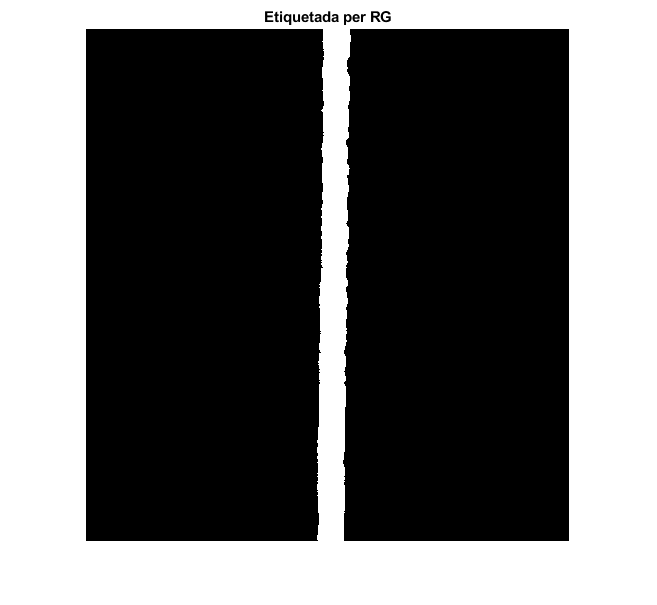

RG(18, 252, 1);
figure, imshow(eti, []), title('Etiquetada per RG')

## Clusters

### 4 clusters

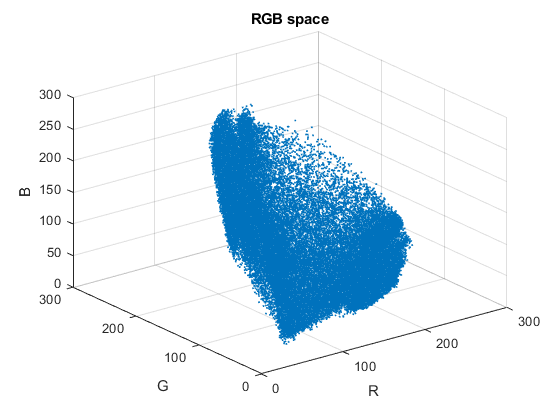

vect = reshape(double(im), MAXFILA*MAXCOL, 3);
figure, scatter3(vect(:, 1), vect(:, 2), vect(:, 3), 1), title('RGB space')
xlabel('R'), ylabel('G'), zlabel('B')

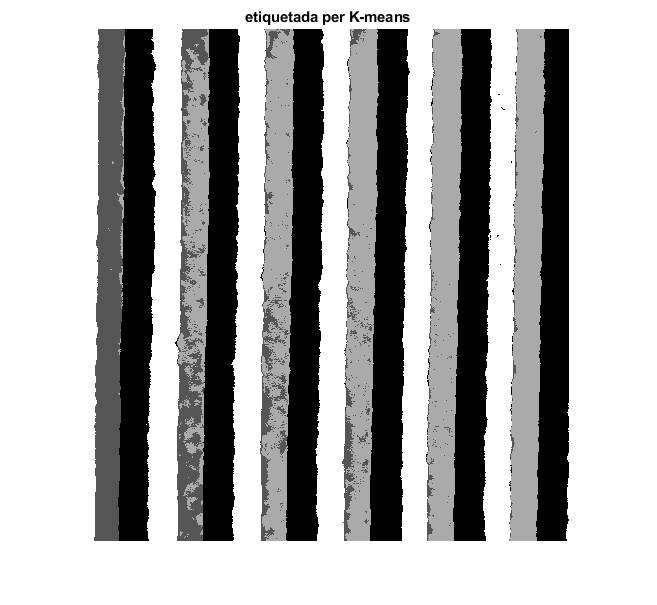

Nclusters = 4;
[cl_eti, cl_ct] = kmeans(vect,Nclusters,'distance', 'cityblock');
eti=reshape(cl_eti,MAXFILA, MAXCOL); 
figure, imshow(eti,[]), title('etiquetada per K-means');

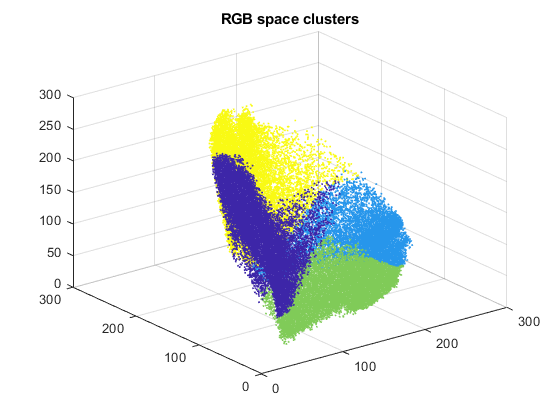

figure, scatter3(vect(:, 1), vect(:, 2), vect(:, 3), 1,cl_eti), title('RGB space clusters');

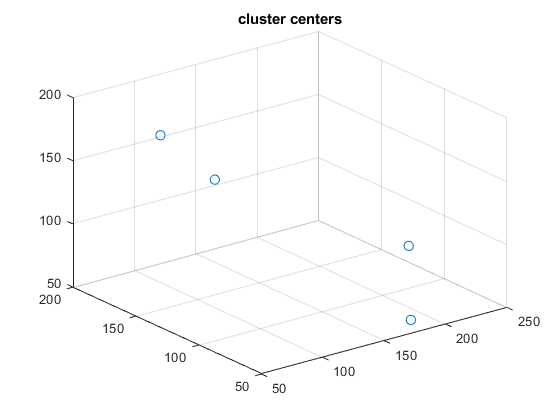

figure, scatter3(cl_ct(:, 1), cl_ct(:, 2), cl_ct(:, 3), 50), title('cluster centers')

### 3 clusters

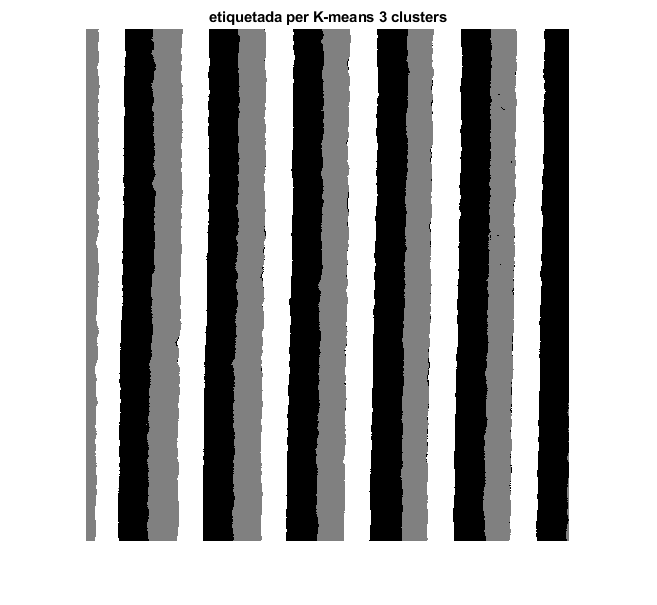

Nclusters = 3;
[cl_eti, cl_ct] = kmeans(vect,Nclusters,'distance', 'cityblock');
eti=reshape(cl_eti,MAXFILA, MAXCOL); 
figure, imshow(eti,[]), title('etiquetada per K-means 3 clusters');

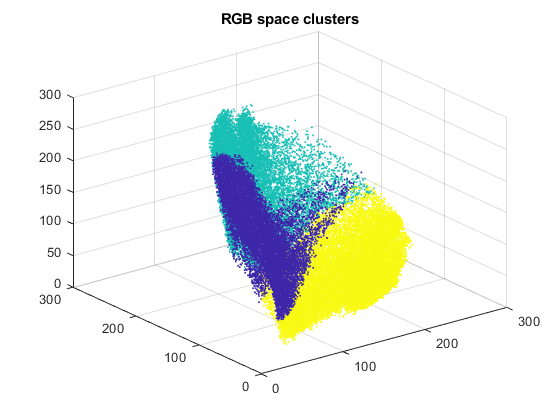

figure, scatter3(vect(:, 1), vect(:, 2), vect(:, 3), 1,cl_eti), title('RGB space clusters');

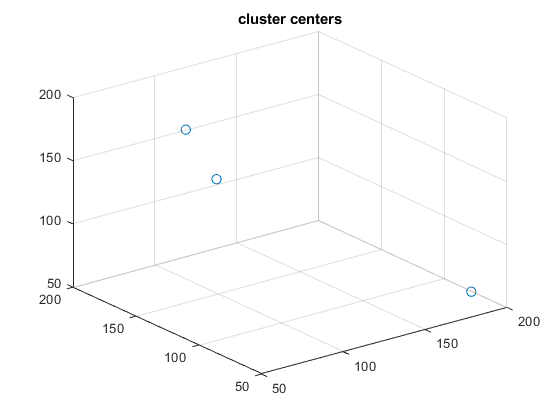

figure, scatter3(cl_ct(:, 1), cl_ct(:, 2), cl_ct(:, 3), 50), title('cluster centers')

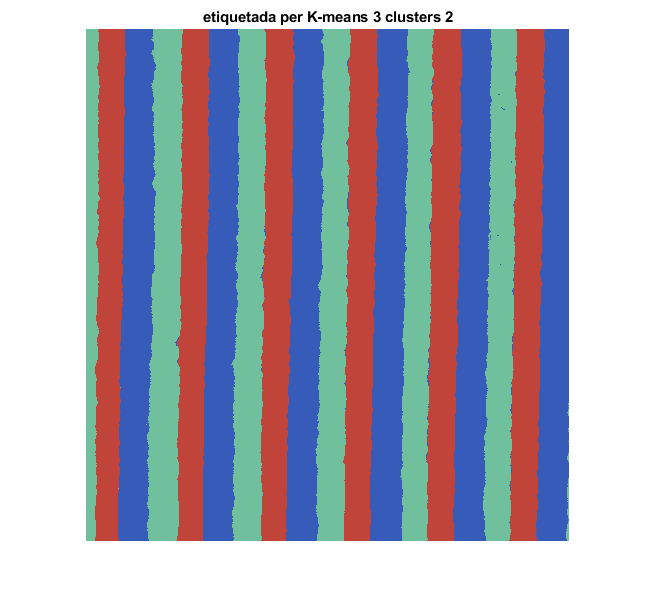

eti2 = ind2rgb(eti, cl_ct/255);
figure, imshow(eti2,[]), title('etiquetada per K-means 3 clusters 2');